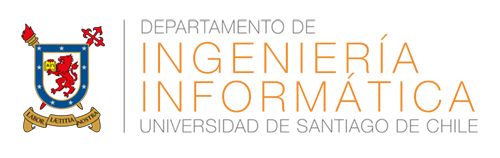

# Evaluación N° 1

## PROCESAMIENTO DE SEÑALES E IMÁGENES

Profesores:

- Violeta Chang C.

- Max Chacón.

Ayudante: Luis Corral

Estudiante: Valentina Paz Campos Olguín

# Generales

 Precaución al reproducir las señales, archivos wav o sus resultados en audífonos o altavoces ya que puede ocasionar daño a su sistema de reproducción o más importante a sus oídos. 

Entregue un archivo .mlx de Matlab sin ningún adjunto (archivos .wav, archivos .m ni otros). Se evalúa los conceptos y fórmulas en formato de texto, los comentarios dentro del código, la exactitud y simpleza del algoritmo y la calidad de los gráficos generados. Muestre solo los valores más importantes.

# Problema 1

Considere la relación $\omega_s = 2\pi f_s$, donde $f_s$ es la frecuencia de muestreo en Hertz. Obtenga la señal del archivo '44100Hz.wav' y su frecuencia de muestreo con el uso de la función [y,Fs] = audioread(filename) de Matlab. Grafique la señal en el tiempo y determine la frecuencia en Hertz $f_0$ de la señal sinusoidal sin utilizar herramientas en el dominio de la frecuencia. Indique si es posible saber la frecuencia de la señal sinusoidal del archivo wav sin saber la frecuencia de muestreo.

**Procedimiento y respuestas:**

Lo primero que se debe realizar es leer el archivo '44100.wav' proporcionado. Esto se puede hacer con la función audioread(<nombre_archivo>). 

Luego, se grafica el tiempo v/s la amplitud de la señal. A primera vista se ve solo un gráfico con forma rectangular ya que la frecuencia es bastante alta. Es decir, las ondulaciones completan un ciclo en un período de tiempo muy corto, por lo que para poder inspeccionar de mejor forma la gráfica se debe colocar un límite en el eje x, así pudiendo visualizar las ondas en cierto intervalo de tiempo.

Ya con esto se puede determinar la frecuencia angular de Nyquist, la cual se calcula multiplicando la frecuencia de muestreo por pi.

Finalmente se tiene que la frecuencia angular de Nyquist de la señal es de 1.3854e+05 [Hz].

Respondiendo a lo último, no se puede saber la frecuencia de señal sinusoidal sin la frecuencia de muestreo. Esto es porque la frecuencia de muestreo es el número de muestras tomadas durante cierto tiempo en una señal. Sin este número, no se sabe cada cuánto tiempo debe tomar una muestra y si este valor varía, da cómo resultado una señal distinta.

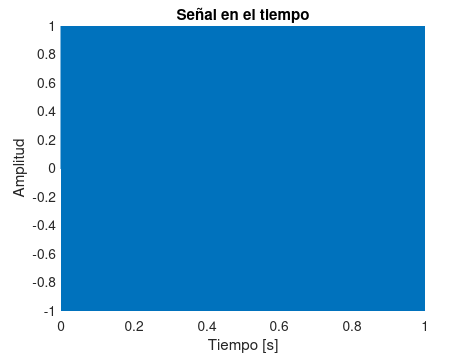

clearvars
% 1. Se lee la señal del archivo '44100Hz.wav', se obtiene 
% la frecuencia de muestreo en la variable Fs y las amplitudes
% en la variable y:
[y, Fs] = audioread('44100Hz.wav');

% 2. Se grafica la señal en el tiempo
time = (0:length(y)-1)/Fs; % Se crea un vector de tiempo
plot(time, y); % Se grafica la señal tiempo v/s amplitudes
xlabel('Tiempo [s]');
ylabel('Amplitud');
title('Señal en el tiempo');

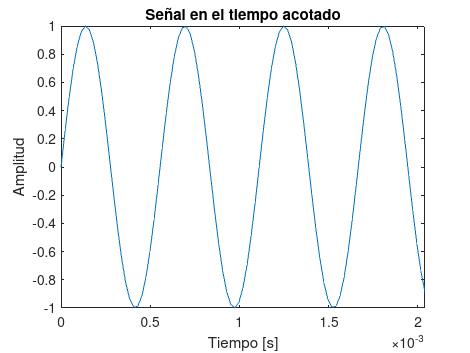


% 3. Se limita el gráfico en el eje x

limit_x = (1/Fs)*90; % Se calcula un límite del eje x para poder 
                      % visualizar mejor la señal
plot(time, y);
xlim([0 limit_x]);
xlabel('Tiempo [s]');
ylabel('Amplitud');
title('Señal en el tiempo acotado');


% 4. Se procede a determinar la frecuencia de Nyquist de
% de la señal sinusoidal.
% Para esto, se multiplica la frecuencia de muestreo por pi.
w0 = Fs * pi;
w0

w0 = 1.3854e+05

% Finalmente, se tiene que la frecuencia angular de Nyquist es:
% 1.3854e+05

# Problema 2

La ecuación diferencial de un sistema compuesto por un filtro RC

$v_o = v_i + RC \frac{d v_o}{dt}$,

donde $v_o$ es el voltaje de salida y $v_i$ es el voltaje de entrada, tiene una conveniente ecuación en diferencias para tiempo discreto:


$$y[n] = x[n] + \alpha y[n-1]$$


A partir de la transformada Z de la ecuación en diferencias presentada, grafique el diagrama de polos y ceros a partir de la función de transferencia $H[z]$ y determine la estabilidad del sistema para $\alpha = -0.5$ argumentando su respuesta. 

**Procedimiento y respuestas:**

Se aplica la transformada Z a la ecuación en diferencias para tiempo discreto, resultando de la siguiente forma:

Y[z] = X[z] - 0.5Y[z](z^-1)

Se ordena la ecuación de la siguiente manera:

H[z] = Y[z]/X[z]

H[z] = z/(z + 0.5)

Luego, se hacen 2 vectores donde se tienen los valores de los coeficientes que acompañan a z, con sus grados ordenados de forma descendente.

La variable b representará al numerador, mientras que la variable a representará al denominador.

Con esto ya se pueden graficar los polos y ceros, pero para calcularlos matemáticamente se hace de la siguiente forma:

Se calcula que valores de z resultan en 0 para el numerador, estos siendo los ceros.

Se calcula que valores de z resultan en 0 para el denominador, estos siendo los polos.

Finalmente, en el gráfico se puede observar que el único polo existente se encuentra dentro del círculo unitario, por lo que es estable.

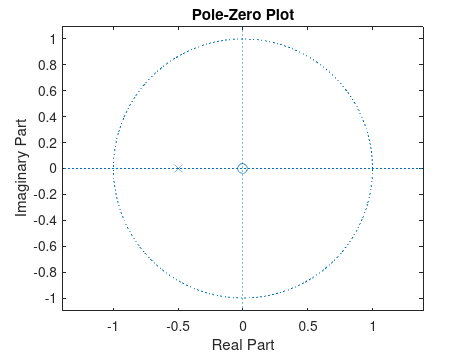

clearvars

% 5. Se grafican los polos y ceros:
b = [1 0];
a = [1 0.5];

figure
zplane(b, a)


% 6. Se obtienen los ceros:
roots(b)

ans = 0


% 7. Se obtienen los polos
roots(a)

ans = -0.5000


% 8. A partir del gráfico: Como el único polo del sistema
% está dentro del círculo unitario, significa que es estable
% para a = -0.5.

# Problema 3

Utilizando la función impz de matlab indicando el número de muestras $n$ y la frecuencia de muestreo en Hertz $f_s$, obtenga la respuesta al impulso $h[n]$ del problema 2. Luego, utilizando la función conv con el parámetro 'same' obtenga la salida del sistema $y[n] = x[n] * h[n]$ donde la señal de entrada $x[n]$ se obtiene desde el archivo 'white_noise_263s_Matlab10_EDIT.wav'.

**Procedimiento y respuestas:**

Se elige la cantidad de muestras que se quieren tomar y una frecuencia de muestreo de 5000 [Hz].

Luego, se determina la respuesta al impulso empleando la variable b (numerador de la transformada Z de la respuesta al impulso), la variable a (denominador), n (número de muestras) y Fs (frecuencia de muestreo dado).

Se procede a leer el archivo 'white_noise_263s_Matlab10_EDIT.wav' para obtener los tiempos y la frecuencia de muestreo de la señal.

Se obtiene la salida del sistema convolucionando x y h con la función 'conv', teniendo como argumento además de la entrada del sistema y la respuesta al impulso, el parámetro 'same'.

Finalmente, se grafican x[n], h[n], y[n]

clearvars
% 1. Se toman los valores del anterior problema
b = [1 0];
a = [1 0.5];

% 2. Se usa impz para obtener la respuesta al impulso
n = 100; % Este es el número de muestras
Fs = 5000; % Frecuencia de muestreo en [Hz]
[h, t] = impz(b, a, n, Fs); 
[x, Fs] = audioread('white_noise_263s_Matlab10_EDIT.wav');

% 3. Se convoluciona la señal de entrada con la respuesta al impulso
y = conv(x, h, 'same');

% 4. Se obtiene la salida del sistema
y

y =    -0.0172
    0.0314
   -0.0499
    0.0318
   -0.0345
   -0.0090
    0.0025
   -0.0044
   -0.0176
    0.0177


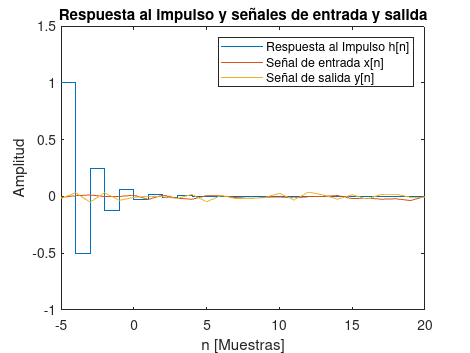


% 5. Modificación para H[z] = z/(z+0.5)
figure
n = -5:94;

% 6. Se asegura que x e y tengan la misma longitud de n
x = x(1:length(n));
y = y(1:length(n));
stairs(n, h, 'DisplayName', 'Respuesta al impulso h[n]')
hold on
xlim([-5 20]) % Se delimitan tanto en x como en y
ylim([-1 1.5])
plot(n, x, 'DisplayName', 'Señal de entrada x[n]') % Se grafica y se muestra por color la señal
plot(n, y, 'DisplayName', 'Señal de salida y[n]')

xlabel('n [Muestras]')% Se indican los títulos de los ejes x e y
ylabel('Amplitud')
title('Respuesta al impulso y señales de entrada y salida')
legend('Location', 'northeast')